clear all
load ARTEMIS.mat;
start=100;%Definisci l'istante iniziale
N=5; %Time horizon
u=[];
%Simuli su finestre di 5 secondi per avere un'idea di come simulerebbe nel
%lungo periodo senza che ci metta 200 ore ogni volta. Non è MPC è solo per
%vedere i risultati pratici
for j=1:18
    %Estrai i sottovettori e ridefinisci gli handle per i sottovettori
    speed=ARTEMIS(1,start-1+j*N:start+N-1+j*N);
    acceleration=ARTEMIS(2,start-1+j*N:start+N-1+j*N);
    gear=ARTEMIS(3,start-1+j*N:start+N-1+j*N);
    StateUpdate=@(input,cur_SOC,i)hev_MPC(speed(i),acceleration(i),gear(i),cur_SOC,input);
    FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
    
    %calcoli la u ottima sull'orizzonte dei 5 secondi
    tic
    opts=optimoptions('fmincon','algorithm','sqp','MaxFunctionEvaluations',1e5,'Display','none');
    toc

    %salvi la u per poi vedere il risultato complessivo
    u=[u;fmincon(FullStateUpdate,0.5*ones(N,1),[],[],[],[],-1*ones(N,1),ones(N,1),[],opts)];
end

Elapsed time is 0.779018 seconds.
Elapsed time is 0.038622 seconds.
Elapsed time is 0.029115 seconds.
Elapsed time is 0.023718 seconds.
Elapsed time is 0.037323 seconds.
Elapsed time is 0.011491 seconds.
Elapsed time is 0.008738 seconds.
Elapsed time is 0.007093 seconds.
Elapsed time is 0.010309 seconds.
Elapsed time is 0.009668 seconds.
Elapsed time is 0.009725 seconds.
Elapsed time is 0.007699 seconds.
Elapsed time is 0.006351 seconds.
Elapsed time is 0.009099 seconds.
Elapsed time is 0.010128 seconds.
Elapsed time is 0.008484 seconds.
Elapsed time is 0.011024 seconds.
Elapsed time is 0.010942 seconds.


%Vedi i risultati utilizzando la u trovata nell'intero orizzonte
speed=ARTEMIS(1,start:start+N-1+j*N);
acceleration=ARTEMIS(2,start:start+N-1+j*N);
gear=ARTEMIS(3,start:start+N-1+j*N);
StateUpdate=@(input,cur_SOC,i)hev_MPC(speed(i),acceleration(i),gear(i),cur_SOC,input);
FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
[cost,I,SOC,mf]=FullStateUpdate(u);
sum(mf)

ans = 0.0021

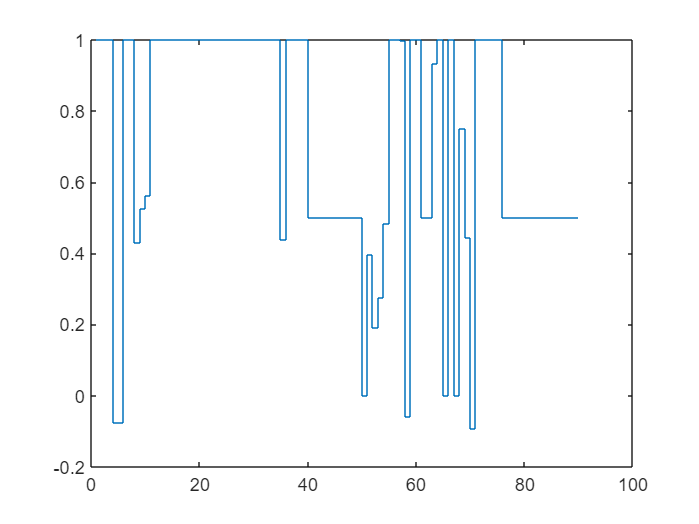

stairs(u)

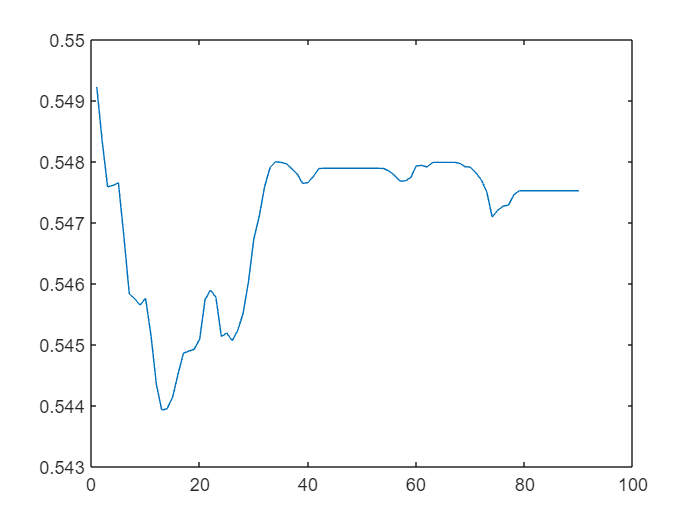

ylabel('u')
plot(SOC)

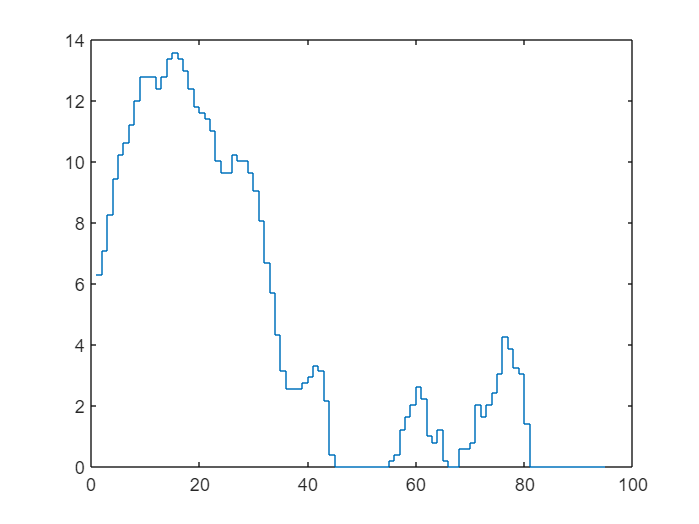

ylabel('SOC')
stairs(speed)

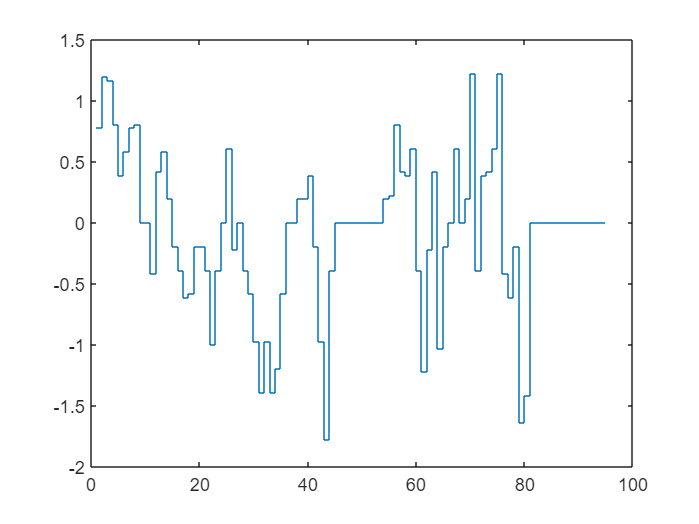

ylabel('speed')
stairs(acceleration)

ylabel('acceleration')